# S10 Filtros digitales

## Importar

Desde osciloscopio Rigol

%Señales con ruido
noise_pink_sin = readmatrix("data/sin_pn.CSV");
noise_white_sin = readmatrix("data/sin_wn.CSV");
fs_noise = 1/1.000E-06 %Hz

fs_noise = 1000000

N_noise = length(noise_white_sin);


Desde la grabación de audio

%Importar audio owl.mp3
[owl,fs_owl] = audioread("data/Owl.wav");
N_owl = length(owl);


Señal del filtro resonante

res_filter = readmatrix("data/scope_csv_27_0.csv");
N_res = length(res_filter);
fs_res = 1/res_filter(1,1);
res_filter = res_filter(:,2);

## Promedio movil

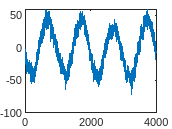

%Antes del promedio móvil
figure
plot(noise_pink_sin)

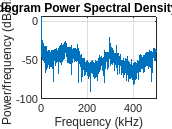


periodogram(noise_pink_sin,rectwin(N_noise),N_noise,fs_noise)

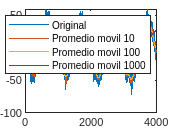


%Aplicar promedio movil y comparar en tiempo y frecuencia

sin_mov_mean_1 = movmean(noise_pink_sin,10);
sin_mov_mean_2 = movmean(noise_pink_sin,100);
sin_mov_mean_3 = movmean(noise_pink_sin,1000);

figure
plot([noise_pink_sin, ...
    sin_mov_mean_1, ...
    sin_mov_mean_2, ...
    sin_mov_mean_3])
legend("Original", ...
    "Promedio movil 10", ...
    "Promedio movil 100", ...
    "Promedio movil 1000")

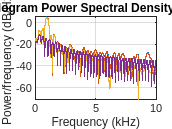



periodogram([noise_pink_sin, ...
    sin_mov_mean_1, ...
    sin_mov_mean_2, ...
    sin_mov_mean_3],rectwin(N_noise),100*N_noise,fs_noise)
xlim([0 10])

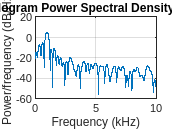


periodogram([noise_pink_sin],rectwin(N_noise),100*N_noise,fs_noise)
xlim([0 10])

## Savitzky-Golay

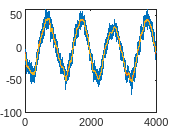

%Aplicar sgolay a una señal sinusoidal ruidosa.
%Comparar resultado contra promedio movil en tiempo y frecuencia
sin_sg_1 = sgolayfilt(noise_pink_sin,3,111);
sin_sg_2 = sgolayfilt(noise_pink_sin,5,111);

figure
plot([noise_pink_sin sin_sg_1 sin_sg_2])

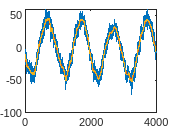


%Comparar con promedio movil
figure
plot([noise_pink_sin sin_mov_mean_2 sin_sg_2])

## Filtro resonante

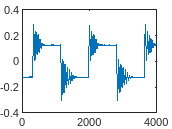

%Determinar la frecuencia de resonancia (oscilacion pequeña) del filtro
%resonante
res_filter_clean = sgolayfilt(res_filter,2,31);


figure 
plot(res_filter_clean)

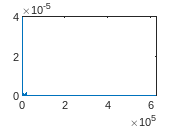


[pxx,f] = periodogram(res_filter_clean,rectwin(N_res),100*N_res,fs_res);
plot(f,pxx)

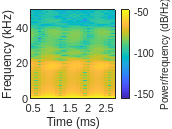


win= N_res*0.3;
overlap = ceil(win*0.9);

spectrogram(res_filter_clean,win,overlap,N_res*1000,fs_res,'yaxis')
ylim([0 50])

## Diseño de filtros

%Diseñar un filtro que elimine exactamente la oscilacion del filtro
%resonante

%filt = designfilt()
filt = designfilt('bandstopiir','PassbandFrequency1',1000,'StopbandFrequency1',1050,'StopbandFrequency2',1950,'PassbandFrequency2',2000,'PassbandRipple1',0.1,'StopbandAttenuation',60,'PassbandRipple2',0.1,'SampleRate',1250000);

## Aplicar filtro

filter(filtro,x)

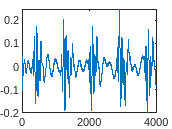

res_filter_filtered = filter(filt,res_filter);

figure
plot(res_filter_filtered)

## Buho

%Mirar el contenido espectral del audio del buho con el periodograma y el
%espectrograma

%Escuchar el audio
%sound()


## Diseño de filtro 2

%Diseñar un filtro para eliminar la banda del buho
%Diseñar un filtro para eliminar la banda de los pajaritos
filt_buho = designfilt('highpassiir','StopbandFrequency',1500,'PassbandFrequency',1600,'StopbandAttenuation',60,'PassbandRipple',1,'SampleRate',22050);
filt_pajaros = designfilt('lowpassiir','PassbandFrequency',1500,'StopbandFrequency',1600,'PassbandRipple',1,'StopbandAttenuation',60,'SampleRate',22050);


## Aplicar filtro 2

%Aplicar ambos filtros

sig_no_buho = filter(filt_buho,owl(:,1));
sig_no_pajaros = filter(filt_pajaros,owl(:,1));

## Verificar resultados

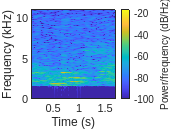

%Escuchar los resultados y visualizarlos con espectrograma y periodograma
%Cuidado, porque la RAM se desborda con los espectrogramas

win= N_owl*0.1;
overlap = ceil(win*0.9);
spectrogram(sig_no_buho,win,overlap,N_owl*10,fs_owl,'yaxis')
set(gca,'CLim',[-100 -17]);

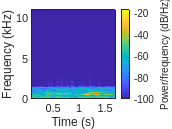



%sound(sig_no_buho,fs_owl)


win= N_owl*0.1;
overlap = ceil(win*0.9);
spectrogram(sig_no_pajaros,win,overlap,N_owl*10,fs_owl,'yaxis')
set(gca,'CLim',[-100 -17]);



%sound(sig_no_pajaros,fs_owl)